## Characteristics of Vector Cross Products 

(1) x X y = -y X x

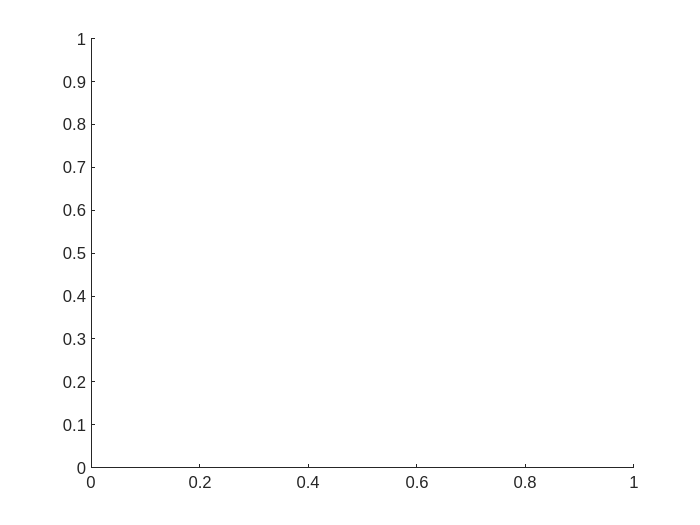

x = [1, 3, 4];
y = [-3, 5, -2];

figure;
hold on


%quiver3(0, 0, 0, x(1), x(2), x(3), 0, "r", LineWidth=2);
%quiver3(0, 0, 0, y(1), y(2), y(3), 0, "b", LineWidth=2);
xcy = cross(x, y);
%quiver3(0, 0, 0, xcy(1), xcy(2), xcy(3), 0, "b", LineWidth=2);
mesh(x,y,xcy);

Error using mesh (line 71)
Z must be a matrix, not a scalar or vector.

% Cross Product Demonstration: x × y = -y × x
% Define vectors
x = [1, 3, 4];
y = [-3, 5, -2];

% Calculate cross products
x_cross_y = cross(x, y);
y_cross_x = cross(y, x);

% Display results to verify the property
disp('Vector x:');

Vector x:


disp(x);

     1     3     4



disp('Vector y:');

Vector y:


disp(y);

    -3     5    -2



disp('x × y:');

x × y:


disp(x_cross_y);

   -26   -10    14



disp('y × x:');

y × x:


disp(y_cross_x);

    26    10   -14



disp('-y × x:');

-y × x:


disp(-y_cross_x);

   -26   -10    14




% Check if x × y = -y × x
if all(abs(x_cross_y - (-y_cross_x)) < 1e-10)
    disp('Verified: x × y = -y × x');
else
    disp('Property not verified');
end

Verified: x × y = -y × x


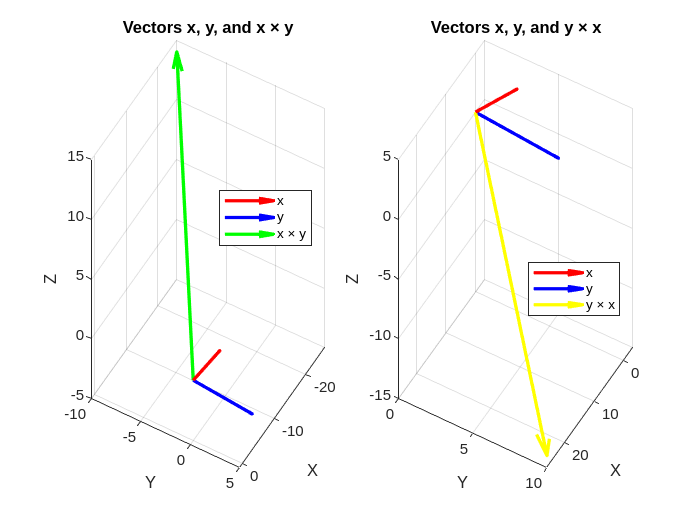


% Visualization
figure;
subplot(1,2,1);
quiver3(0, 0, 0, x(1), x(2), x(3), 0, 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, y(1), y(2), y(3), 0, 'b', 'LineWidth', 2);
quiver3(0, 0, 0, x_cross_y(1), x_cross_y(2), x_cross_y(3), 0, 'g', 'LineWidth', 2);
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Vectors x, y, and x × y');
legend('x', 'y', 'x × y', 'Location', 'best');
view(120, 30);

subplot(1,2,2);
quiver3(0, 0, 0, x(1), x(2), x(3), 0, 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, y(1), y(2), y(3), 0, 'b', 'LineWidth', 2);
quiver3(0, 0, 0, y_cross_x(1), y_cross_x(2), y_cross_x(3), 0, 'y', 'LineWidth', 2);
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Vectors x, y, and y × x');
legend('x', 'y', 'y × x', 'Location', 'best');
view(120, 30);

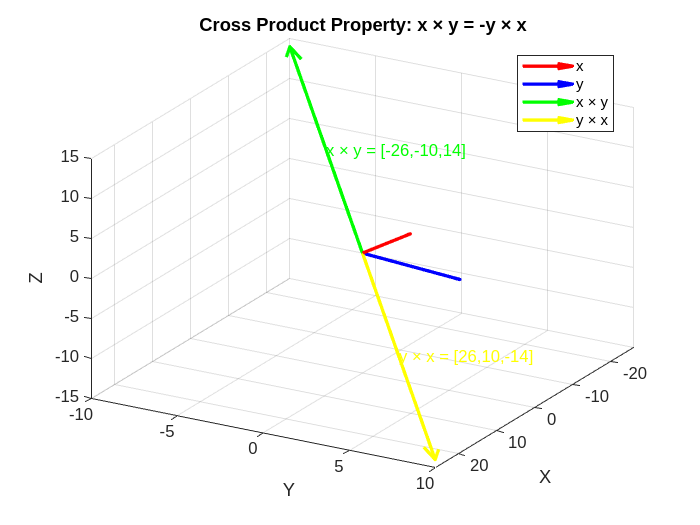


% Combined view showing anti-commutativity
figure;
quiver3(0, 0, 0, x(1), x(2), x(3), 0, 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, y(1), y(2), y(3), 0, 'b', 'LineWidth', 2);
quiver3(0, 0, 0, x_cross_y(1), x_cross_y(2), x_cross_y(3), 0, 'g', 'LineWidth', 2);
quiver3(0, 0, 0, y_cross_x(1), y_cross_x(2), y_cross_x(3), 0, 'y', 'LineWidth', 2);
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Cross Product Property: x × y = -y × x');
legend('x', 'y', 'x × y', 'y × x', 'Location', 'best');
view(120, 30);

% Add text annotations to explain the results
text(x_cross_y(1)/2, x_cross_y(2)/2, x_cross_y(3)/2, 'x × y = [-26,-10,14]', 'Color', 'g');
text(y_cross_x(1)/2, y_cross_x(2)/2, y_cross_x(3)/2, 'y × x = [26,10,-14]', 'Color', 'y');